### MaxIter

- Wykresy poprawy

- Histogramy

- Tabela zestawieniowa

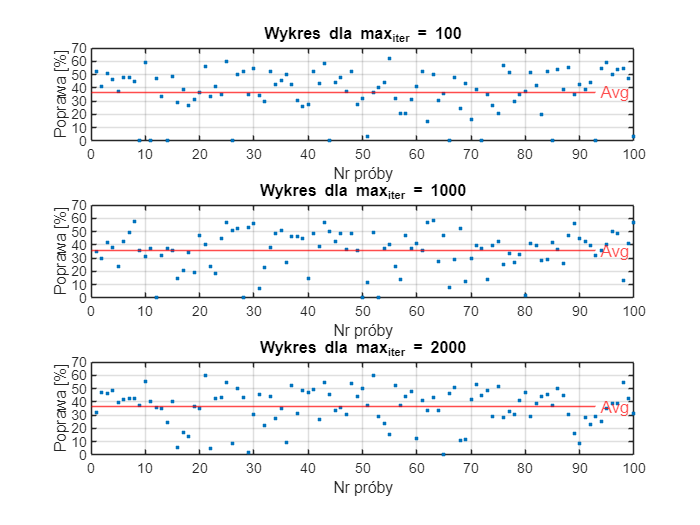

clear all; %#ok<CLALL>
load("results.mat")

max_iter_100_rel_imp = maxIterData(maxIterData.ExperimentName == 100, {'RelativeImprovement'});
max_iter_1000_rel_imp = maxIterData(maxIterData.ExperimentName == 1000, {'RelativeImprovement'});
max_iter_2000_rel_imp = maxIterData(maxIterData.ExperimentName == 2000, {'RelativeImprovement'});

max_iter_100_rel_imp.RelativeImprovement = max_iter_100_rel_imp.RelativeImprovement * 100;
max_iter_1000_rel_imp.RelativeImprovement = max_iter_1000_rel_imp.RelativeImprovement * 100;
max_iter_2000_rel_imp.RelativeImprovement = max_iter_2000_rel_imp.RelativeImprovement * 100;


max_iter_100_rel_imp_avg = mean(max_iter_100_rel_imp.RelativeImprovement);
max_iter_1000_rel_imp_avg = mean(max_iter_1000_rel_imp.RelativeImprovement);
max_iter_2000_rel_imp_avg = mean(max_iter_2000_rel_imp.RelativeImprovement);

max_iter_100_rel_imp_std = std(max_iter_100_rel_imp.RelativeImprovement);
max_iter_1000_rel_imp_std = std(max_iter_1000_rel_imp.RelativeImprovement);
max_iter_2000_rel_imp_std = std(max_iter_2000_rel_imp.RelativeImprovement);

max_iter_names = [100; 1000; 2000;];
max_iter_avgs = [max_iter_100_rel_imp_avg; max_iter_1000_rel_imp_avg; max_iter_2000_rel_imp_avg];
max_iter_stds = [max_iter_100_rel_imp_std; max_iter_1000_rel_imp_std; max_iter_2000_rel_imp_std];

max_iter_comparison = table(max_iter_names, max_iter_avgs, max_iter_stds, 'VariableNames', {'max_iter', 'avg', 'std'});

max_value = max([max(max_iter_100_rel_imp.RelativeImprovement), ...
    max(max_iter_1000_rel_imp.RelativeImprovement), ...
    max(max_iter_2000_rel_imp.RelativeImprovement)]);
y_axis_limit_plot = ceil(max_value / 10) * 10;

bin_width = 5;
max_count_100 = max(histcounts(max_iter_100_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_1000 = max(histcounts(max_iter_1000_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_2000 = max(histcounts(max_iter_2000_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
y_axis_limit_hist = max([max_count_100, max_count_1000, max_count_2000]) + 10;

figure;

subplot(3, 1, 1);
plot(max_iter_100_rel_imp.RelativeImprovement, '.');
yline(max_iter_100_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla max_iter = 100');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 2);
plot(max_iter_1000_rel_imp.RelativeImprovement, '.');
yline(max_iter_1000_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla max_iter = 1000');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 3);
plot(max_iter_2000_rel_imp.RelativeImprovement, '.');
yline(max_iter_2000_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla max_iter = 2000');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

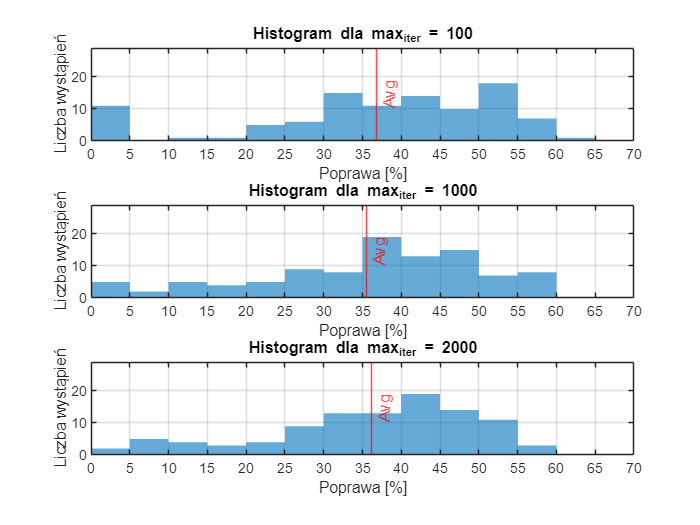


figure;

% Histogram dla max_iter_100_rel_imp
subplot(3, 1, 1);
histogram(max_iter_100_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(max_iter_100_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla max_iter = 100');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla max_iter_1000_rel_imp
subplot(3, 1, 2);
histogram(max_iter_1000_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(max_iter_1000_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla max_iter = 1000');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla max_iter_2000_rel_imp
subplot(3, 1, 3);
histogram(max_iter_2000_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(max_iter_2000_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla max_iter = 2000');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);


max_iter_comparison

max_iter_comparison = 3×3 table
    max_iter     avg       std  
    ________    ______    ______

       100      36.868     16.58
      1000      35.533    14.721
      2000      36.133    13.768
